data = data5(end-499:end,:);
% Indicador R datos originales
C = cov(data);
CI = inv(C);
d1 = diag(C);
d2 = diag(CI);
R = 1 - 1./(d1.*d2)

R =     0.7949
    0.7234
    0.6052
    0.5482
    0.8139


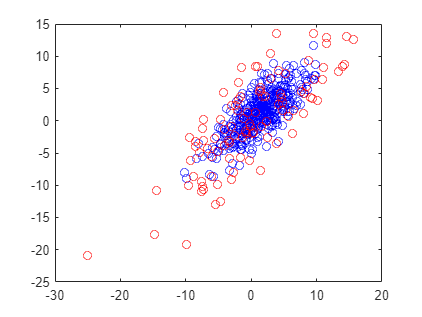

D = mahal(data,data);
plot(data(:,1),data(:,2), 'ob')
hold on;
pc = prctile(D,80);
I = find(D>pc);
plot(data(I,1),data(I,2),'or')
hold off;

data(I,:) = [];

%Indicador R datos recortados
C = cov(data);
CI = inv(C);
d1 = diag(C);
d2 = diag(CI);
R = 1 - 1./(d1.*d2)

R =     0.7750
    0.7117
    0.6772
    0.6012
    0.8055
